% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du troisième bras
a5 = 2; % Longueur du troisième bras

% Définir la position désirée de l'effecteur
x_desired = 3;
y_desired = 7;


%VISUALISATION ESPACE DE TRAVAIL ET POINT CIBLE
% Initialiser une figure
figure;
hold on;
% % Définir le rayon et le centre du cercle
% centre = [0, 0];
% rayon_espace_travail = sum([a1, a2, a3, a4, a5]);
% 
% % Créer les coordonnées du cercle
% theta = linspace(0, 2*pi, 100);
% x_cercle = rayon_espace_travail * cos(theta) + centre(1);
% y_cercle = rayon_espace_travail * sin(theta) + centre(2);
% 
% % Remplir le cercle avec une couleur spécifique
% fill(x_cercle, y_cercle, 'b', 'EdgeColor', 'b', 'FaceAlpha', 0.2);

%Tracer le point désiré en rouge
plot(x_desired, y_desired, 'ro', 'MarkerSize', 10, 'DisplayName', 'Point désiré');



%ESPACE DE TRAVAIL ET VERIFICATION

% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];
% Définir la grille d'angles d'articulation
theta1_range = linspace(-(5*pi)/2, (5*pi)/2, 5);
theta2_range = linspace(0, pi/2, 5);
theta3_range = linspace(0, pi/2, 5);
theta4_range = linspace(0, pi/2, 5);
theta5_range = linspace(0, pi/2, 5);
% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                for m = 1:length(theta5_range)
                    % Calculer les coordonnées de l'effecteur
                    x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));

                    % Ajouter les coordonnées à la liste
                    reachable_points = [reachable_points; x, y];
                end
            end
        end
    end
end
%Tracer le nuage de points représentant l'espace de travail atteignable
scatter(reachable_points(:, 1), reachable_points(:, 2), 1, 'filled');
%disp('Limites de lespace de travail');
min_x = min(reachable_points(:, 1))

min_x = -10.4142

max_x = max(reachable_points(:, 1))

max_x = 11

min_y = min(reachable_points(:, 2))

min_y = -11

max_y = max(reachable_points(:, 2))

max_y = 11


% Vérifier si le point désiré est dans l'espace de travail
if x_desired < min_x || x_desired > max_x || y_desired < min_y || y_desired > max_y
    disp('Le point désiré est en dehors de l''espace de travail du robot.');
    return; % Sortir du programme
else
    disp('Le point désiré est dans l''espace de travail du robot. Continuer le calcul des angles d''articulation.');
    % Ajoutez votre code pour continuer le calcul des angles d'articulation ici
end

Le point désiré est dans l'espace de travail du robot. Continuer le calcul des angles d'articulation.




% % Calcul de la distance entre le point et le centre du cercle
% distance = sqrt((x_desired - centre(1))^2 + (y_desired - centre(2))^2);
% 
% % Vérification si le point est à l'intérieur du cercle
% if distance <= rayon_espace_travail
%     disp('Le point est à l''intérieur du cercle.');
% else
%     disp('Le point est à l''extérieur du cercle.');
% end


%RECHERCHE DE SOLUTIONS
% Initialiser une liste pour stocker les configurations atteignables
all_solutions = [];

% Définir une fonction pour la cinématique inverse
inverse_kinematics = @(x_desired, y_desired) find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired);

% Nombre de configurations à rechercher
num_configurations = 4; % Modifier selon vos besoins

% Recherche des configurations
for i = 1:num_configurations
    % Utiliser la fonction de cinématique inverse pour trouver une solution
    [theta1, theta2, theta3, theta4, theta5] = inverse_kinematics(x_desired, y_desired);
    
    % Calculer les coordonnées de l'effecteur pour cette configuration
    x_effecteur = a1 * cos(theta1) + a2 * cos(theta1 + theta2) + a3 * cos(theta1 + theta2 + theta3) + a4 * cos(theta1 + theta2 + theta3 + theta4) + a5 * cos(theta1 + theta2 + theta3 + theta4+ theta5);
    y_effecteur = a1 * sin(theta1) + a2 * sin(theta1 + theta2) + a3 * sin(theta1 + theta2 + theta3) + a4 * sin(theta1 + theta2 + theta3 + theta4) + a5 * sin(theta1 + theta2 + theta3 + theta4+ theta5);
    
    % Vérifier si les coordonnées de l'effecteur sont proches du point désiré
    if sqrt((x_effecteur - x_desired)^2 + (y_effecteur - y_desired)^2) < tolerance
        % Stocker la solution et les coordonnées de l'effecteur
        all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x_effecteur, y_effecteur]];
    end
    
end 

Convergence atteinte.
Convergence atteinte.


% Afficher toutes les configurations trouvées
disp('Configurations possibles du robot pour la position désirée :');

Configurations possibles du robot pour la position désirée :


disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculated   Y_calculated');

    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculated   Y_calculated


disp(all_solutions);

    1.8558    5.7540    4.9111    0.3370    1.8475    3.0000    7.0000
    1.2499    5.7940    0.4633    5.7744    2.5058    3.0000    7.0000



% Convertir les angles d'articulation en degrés pour affichage
all_solutions_deg = all_solutions(:, 1:5); % Copier les angles en radians
all_solutions_deg(:, 1:5) = rad2deg(all_solutions_deg(:, 1:5)); % Convertir en degrés

% Afficher toutes les configurations trouvées en degrés
disp('Configurations possibles du robot pour la position désirée (en degrés) :');

Configurations possibles du robot pour la position désirée (en degrés) :


disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculated   Y_calculated');

    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculated   Y_calculated


disp(all_solutions_deg);

  106.3297  329.6809  281.3848   19.3106  105.8556
   71.6134  331.9696   26.5470  330.8474  143.5698



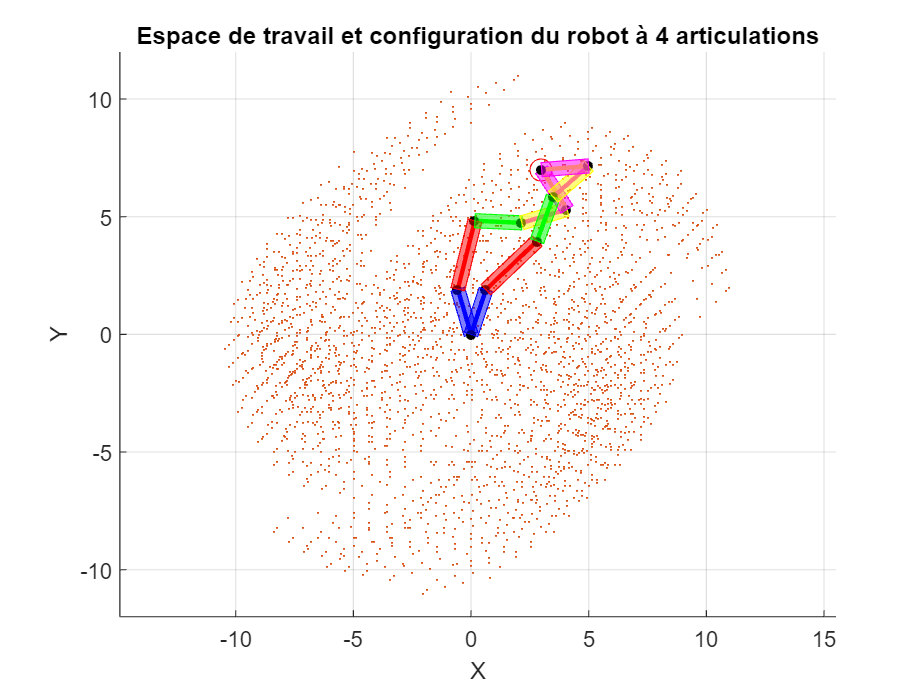





%VISUALISER LE ROBOT, LE POINT DESIRE, ET L'ESPACE DE TRAVAIL
% Définir les couleurs pour chaque type de segment
color_segment_OA = 'b'; % Segment OA
color_segment_AB = 'r'; % Segment AB
color_segment_BC = 'g'; % Segment BC
color_segment_CD = 'm'; % Segment CD
color_segment_DE = 'y'; % Segment DE

% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'DisplayName', ['Segment OA - Solution ', num2str(i)]); % Segment OA
    plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'DisplayName', ['Segment AB - Solution ', num2str(i)]); % Segment AB
    plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'DisplayName', ['Segment BC - Solution ', num2str(i)]); % Segment BC
    plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'DisplayName', ['Segment CD - Solution ', num2str(i)]); % Segment BC
    plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'DisplayName', ['Segment DE - Solution ', num2str(i)]); % Segment BC
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations

    % Ajouter des rectangles autour des segments
    rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
    drawSegmentRectangle(O, A, rectWidth, 'b');
    drawSegmentRectangle(A, B, rectWidth, 'r');
    drawSegmentRectangle(B, C, rectWidth, 'g');
    drawSegmentRectangle(C, D, rectWidth, 'y');
    drawSegmentRectangle(D, E, rectWidth, 'm');

end 


% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Espace de travail et configuration du robot à 4 articulations');
xlabel('X');
ylabel('Y');
% Légende
%legend;

% Affichage de la grille
grid on;

hold off; 

% Fonction cinematique inverse et pour créer un rectangle autour d'un segment

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5);
end



function [theta1, theta2, theta3, theta4, theta5] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired)
    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.00001;
    max_iterations = 100;

    % Initialiser les angles d'articulation
    theta1 = rand * 2 * pi; % Initialiser à des valeurs aléatoires
    theta2 = rand * 2 * pi;
    theta3 = rand * 2 * pi;
    theta4 = rand * 2 * pi;
    theta5 = rand * 2 * pi;

    % Boucle d'itération pour trouver les angles d'articulation
    for i = 1:max_iterations
        % Calculer les équations directes de cinématique directe
        x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
        y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
        % Calculer l'erreur de position
        error_x = x_desired - x;
        error_y = y_desired - y;
        error = [error_x; error_y];

        % Calculer les dérivées partielles
        dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
        dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
        dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        % Construire la Jacobienne
        J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
         dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];

        % Vérifier la convergence
        if norm(error) < tolerance
            disp('Convergence atteinte.');
            break;
        end

        % Calculer la variation des angles d'articulation
        delta_theta = pinv(J) * error;

        % Mettre à jour les angles d'articulation
        theta1 = theta1 + delta_theta(1);
        theta2 = theta2 + delta_theta(2);
        theta3 = theta3 + delta_theta(3);
        theta4 = theta4 + delta_theta(4);
        theta5 = theta5 + delta_theta(5);
        % Correction des angles d'articulation pour les maintenir entre 0 et 2*pi
        theta1 = mod(theta1, 2*pi);
        theta2 = mod(theta2, 2*pi);
        theta3 = mod(theta3, 2*pi);
        theta4 = mod(theta4, 2*pi);
        theta5 = mod(theta5, 2*pi);
        
        % Retourner les angles d'articulation corrigés
        [theta1, theta2, theta3, theta4, theta5];
        
       
    end
end